# COVID-2019 data for Germany

Case data obtained from John Hopkins university: [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

## Initialisation

clearvars;close all;clc;
% Download the data and read them with the function getDataCOVID
[tableConfirmed,tableDeaths,tableRecovered,time_raw] = getDataCOVID();
fprintf(['Most recent update: ',datestr(time_raw(end)),'\n'])

Most recent update: 19-Jul-2021


Location = 'Germany';
try
    indR = find(contains(tableRecovered.CountryRegion,Location)==1 & (tableRecovered.ProvinceState.ismissing()==1))
    indC = find(contains(tableConfirmed.CountryRegion,Location)==1 & (tableConfirmed.ProvinceState.ismissing()==1))
    indD = find(contains(tableDeaths.CountryRegion,Location)==1 & (tableDeaths.ProvinceState.ismissing()==1))
catch exception
    searchLoc = strfind(tableRecovered.CountryRegion,Location);
    indR = find(~cellfun(@isempty,searchLoc)) ; 
    
    searchLoc = strfind(tableConfirmed.CountryRegion,Location);
    indC = find(~cellfun(@isempty,searchLoc)) ; 
    
    searchLoc = strfind(tableDeaths.CountryRegion,Location);
    indD = find(~cellfun(@isempty,searchLoc));    
end

indR = 121

indC = 136

indD = 136

indR = indR(1);
indD = indD(1);
indC = indC(1);

Recovered_raw = table2array(tableRecovered(indR,5:end));
Deaths_raw = table2array(tableDeaths(indD,5:end));
Confirmed_raw = table2array(tableConfirmed(indC,5:end));

## Choose Initial and final time

wave_num = 2;

if wave_num == 1                   % first wave
    tStart = datetime(2020,03,01); 
    tEnd = datetime(2020,05,31);
elseif wave_num == 2
    tStart = datetime(2020,09,01); % second wave
    tEnd = datetime(2020,12,01);  
end

% model prediction ability test
tStart_pred = datetime(2020, 12, 02);
tEnd_pred = datetime(2020, 12, 11);
indT_pred = find(time_raw >= tStart_pred & time_raw <= tEnd_pred);
time_pred = time_raw(indT_pred);
Recovered_pred = Recovered_raw(indT_pred);
Deaths_pred = Deaths_raw(indT_pred);
Confirmed_pred = Confirmed_raw(indT_pred);
Active_pred = Confirmed_pred - Deaths_pred - Recovered_pred;

indT = find(time_raw>=tStart & time_raw <=tEnd);
Recovered=Recovered_raw(indT);
Deaths = Deaths_raw(indT);
time = time_raw(indT);
Confirmed = Confirmed_raw(indT);

if isempty(Confirmed)
    warning('"Confirmed" is an empty array. Check the value of "minNum". Computation aborted.')
    return
end

GermanyNPIs = readtable('DataCovid/Germany_NPIs.xlsx');
NPIs = table2array(GermanyNPIs);     % Germany NPIs
Npop = 0.8e8;                        % Germany population

## Fitting of the generalized SEIR model to the real data

Fitting to the 1st wave and the 2nd wave

if wave_num == 1
    
    % Definition of the first estimates for the parameters
    alpha_guess = 0.1;               % protection rate 0.06, 0.1
    beta_guess = 1.0;                % Infection rate
    LT_guess = 5;                    % latent time in days
    Q_guess = 0.1;                   % rate at which infectious people enter in quarantine
    lambda_guess = [0.01,0.001,10];  % recovery rate
    kappa_guess = [0.001,0.001,10];  % death rate
    tau_guess = 0.1;
    time_delay_guess = 5;
    NPI_guess = [-3, -3, -3, -3, -3];

    guess = [alpha_guess,...
             beta_guess,...
             1/LT_guess,...
             Q_guess,...
             lambda_guess,...
             kappa_guess,...
             tau_guess,...
             time_delay_guess,...
             NPI_guess];

    % Initial conditions
    Q0 = Confirmed(1)-Recovered(1)-Deaths(1);
    I0 = 0.1*Q0; % Initial number of infectious cases. Unknown but unlikely to be zero.
    E0 = 0.1*Q0; % Initial number of exposed cases. Unknown but unlikely to be zero.
    R0 = Recovered(1);
    D0 = Deaths(1);
    C0 = 0.1*Q0;
   
    Active = Confirmed-Recovered-Deaths;
    Active(Active<0) = 0; % No negative number possible
    [alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,lambdaFun,kappaFun,tau1,time_delay1,NPI_matrix] = ...
        fit_SEIQRDP_1(Active,Recovered,Deaths,Npop,E0,I0,C0,time,guess,NPIs);
    
elseif wave_num == 2
    % Definition of the first estimates for the parameters
    alpha_guess = 0.1;              % protection rate
    beta_guess = 1.0;               % Infection rate
    LT_guess = 5;                   % latent time in days
    Q_guess = 0.1;                  % rate at which infectious people enter in quarantine
    lambda_guess = [0.01,0.001,10]; % recovery rate
    kappa_guess = [0.001,0.001,10]; % death rate
    tau_guess = 0.1; 
    time_delay_guess = 7;
    NPI_guess = [-3, -3, -3, -3];

    guess = [alpha_guess,...
             beta_guess,...
             1/LT_guess,...
             Q_guess,...
             lambda_guess,...
             kappa_guess,...
             tau_guess,...
             time_delay_guess,...
             NPI_guess];


    % Initial conditions
    Q0 = Confirmed(1)-Recovered(1)-Deaths(1);
    I0 = 0.1*Q0; % Initial number of infectious cases. Unknown but unlikely to be zero.
    E0 = 0.1*Q0; % Initial number of exposed cases. Unknown but unlikely to be zero.
    R0 = Recovered(1);
    D0 = Deaths(1);
    C0 = 0.1*Q0; % Initial number of confined cases. Unknown but unlikely to be zero.
   
    Active = Confirmed-Recovered-Deaths;
    Active(Active<0) = 0; % No negative number possible
    [alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,lambdaFun,kappaFun,tau1,time_delay1,NPI_matrix] = ...
        fit_SEIQRDP_2(Active,Recovered,Deaths,Npop,E0,I0,C0,time,guess,NPIs);
    
 end   


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0         17     3.35157e+16                      2.65e+17
     1         34     2.33685e+15        2.97583       4.25e+16      
     2         51     2.17354e+14      0.0321207       5.85e+15      
     3         68     2.37202e+13        4.55982       8.35e+14      
     4         85     2.06324e+12        2.10699       1.19e+14      
     5        102     1.68826e+11        1.59918       1.35e+13      
     6        119     4.92056e+10        3.35687       3.61e+12      
     7        136     4.77516e+10    0.000338335       1.53e+11      
     8        153     4.34319e+10        5.04991       1.93e+12      
     9        170     3.12697e+10        6.08231       2.17e+12      
    10        187     3.12697e+10        6.34899       2.17e+12      
    11        204     2.54352e+10        1.58725       7.54e+11      
    12        221     2.54352e+1

## Simulate the epidemy outbreak based on the fitted parameters

dt = 1;     % time step
% time1 = datetime(time(1), 'Locale', 'en_US'):dt:datetime(time(end), 'Locale', 'en_US');
time1 = datetime(time(1), 'Locale', 'en_US'):dt:datetime(time(end)+datenum(10), 'Locale', 'en_US');  % prediction
N = numel(time1);
t = [0:N-1].*dt;

[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,tau1,time_delay1,NPI_matrix,...
                            NPIs,Npop,E0,I0,Q0,R0,D0,C0,t,lambdaFun,kappaFun);

## Display the fitted and measured death and recovery rates

w =      1     2     3     4     5     6     7     8     9    10    11    12    13


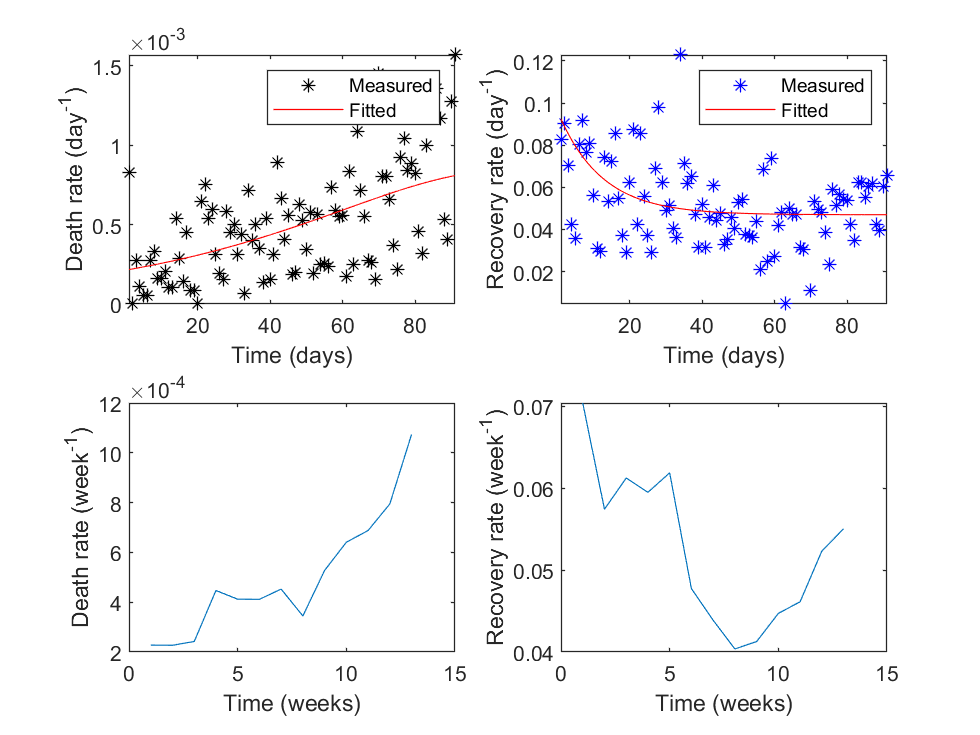

checkRates(time,Active,Recovered,Deaths,kappaFun,lambdaFun,Kappa1,Lambda1);

## Comparison of the fitted and real data

Active cases = Confirmed-Deaths-Recovered (database) = Quarantined (SEIQRDP model)

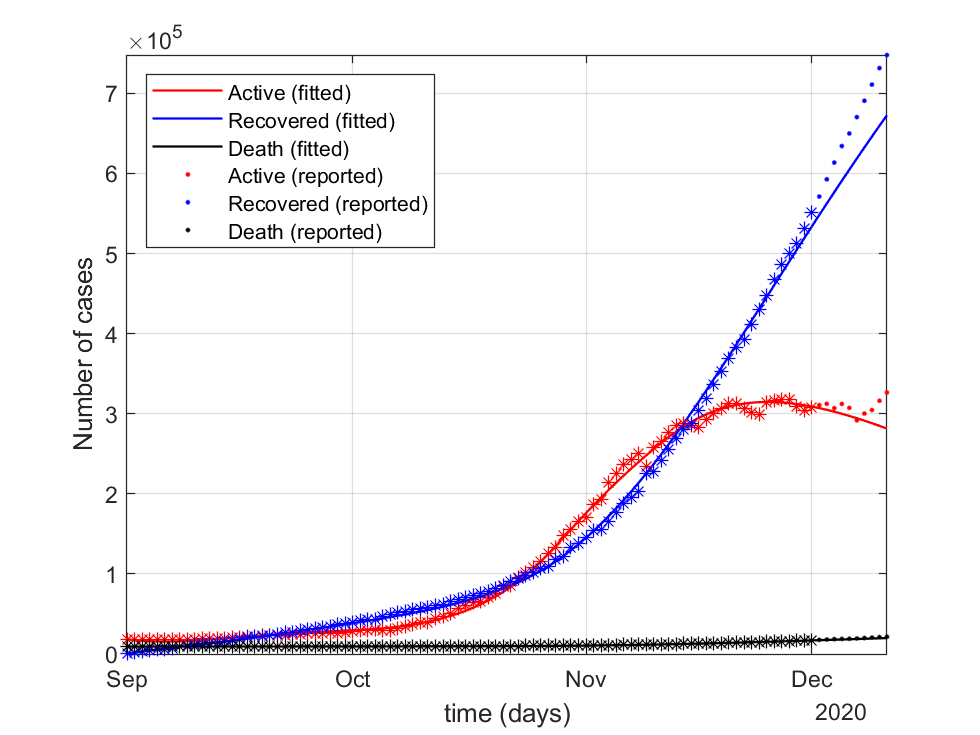

clf;close all;
clear legend;
figure
f1 = semilogy(time1,Q,'r',time1,R-R(1),'b',time1,D,'k');
hold on
semilogy(time_pred,Active_pred,'r.',time_pred,Recovered_pred-Recovered(1),'b.',time_pred,Deaths_pred,'k.');
hold on
semilogy(time,Active,'r*',time,Recovered-Recovered(1),'b*',time,Deaths,'k*');
ylabel('Number of cases')
xlabel('time (days)')
leg = {'Active (fitted)',...
       'Recovered (fitted)','Death (fitted)',...
       'Active (reported)','Recovered (reported)','Death (reported)'};
legend(leg{:},'location','northwest')
set(gcf,'color','w')
set(f1, 'linewidth', 1)
grid on
axis tight
set(gca,'yscale','lin') 

% RMSE 
% Active
rmse_active = sqrt(mean((Active_pred - Q(end-9:end)).^2));
mape_active = mean(abs((Active_pred - Q(end-9:end))./Active_pred))*100;
% Recovered
Recovered_tmp = Recovered_pred - Recovered(1);
R_tmp = R - R(1);
rmse_recovered = sqrt(mean(((Recovered_pred-Recovered(1)) - (R(end-9:end)-R(1))).^2));
mape_recovered = mean(abs((Recovered_tmp - R_tmp(end-9:end))./Recovered_tmp))*100;
% Decreased
rmse_death = sqrt(mean((Deaths_pred - D(end-9:end)).^2));
mape_death = mean(abs((Deaths_pred - D(end-9:end))./Deaths_pred))*100;

rmse_active

rmse_active = 1.9270e+04

mape_active

mape_active = 4.5252

rmse_recovered

rmse_recovered = 5.2709e+04

mape_recovered

mape_recovered = 7.4034

rmse_death

rmse_death = 997.7651

mape_death

mape_death = 4.6094

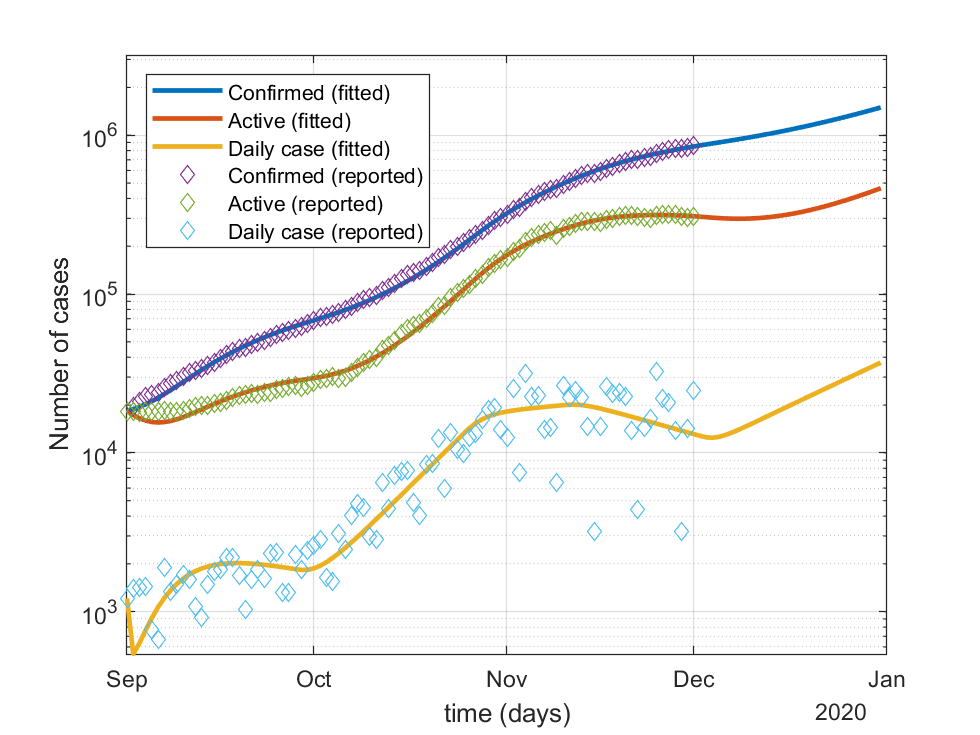

clf;close all;
clear legend;
clear daily_new_case_fit;
figure

% fitted daily_new_case
confirm_fit = R + D + Q;
daily_new_case_fit(2:N) = confirm_fit(2:end) - confirm_fit(1:N-1);
daily_new_case_fit(1) = confirm_fit(1) - 244802;
% observed daily_new_case
daily_new_case_obsv(2:92) = Confirmed(2:end) - Confirmed(1:91);
daily_new_case_obsv(1) = Confirmed(1) - 244802;

f1 = semilogy(time1, (R-R(1)+D-D(1)+Q), time1, Q, time1, daily_new_case_fit);
hold on
semilogy(time, (Recovered-Recovered(1) + Deaths-Deaths(1) + Active), 'd', time, Active, 'd', time, daily_new_case_obsv, 'd')
ylim([0,0.04*Npop])
ylabel('Number of cases')
xlabel('time (days)')
leg = {'Confirmed (fitted)', 'Active (fitted)', 'Daily case (fitted)',...
       'Confirmed (reported)', 'Active (reported)', 'Daily case (reported)'};
legend(leg{:},'location','northwest')
set(gcf,'color','w')
set(f1, 'linewidth', 2)
grid on

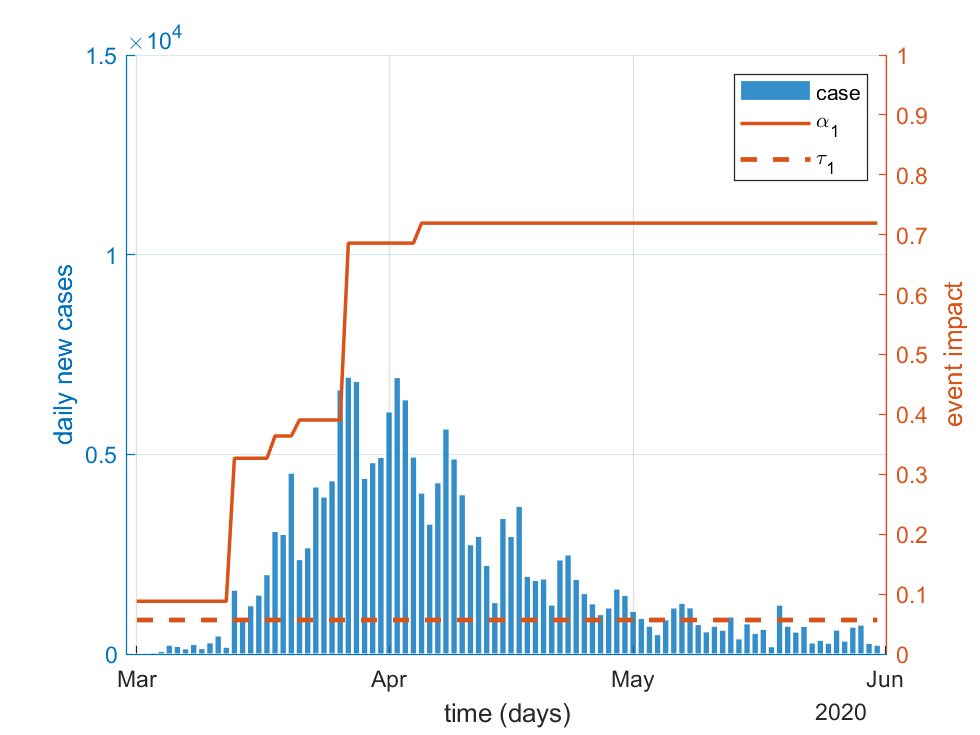

% the 1st wave
clf; close all;
clear impact_alpha_1;
clear impact_tau_1;
clear legend;

% figure: align event impact with COVID-19 curve
time_delay = round(time_delay1);

impact_alpha_1 = ones(1, 92) * alpha1;
impact_tau_1 = ones(1, 92) * tau1;

NPI_ind = 1;
alp_ind = 1;
tau_ind = 1;

for ii=1:92
    if ii == 1
        impact_alpha_1(ii) = alpha1;
        impact_tau_1(ii) = tau1;
    else
        % update alpha and tau with NPIs
        if NPIs(ii, 1) == 1        % control event        
            impact_alpha_1(alp_ind + 1 : ii + time_delay - 1) = impact_alpha_1(alp_ind);
            impact_alpha_1(ii + time_delay) = impact_alpha_1(alp_ind) + NPI_matrix(NPI_ind);
            NPI_ind = NPI_ind + 1;
            alp_ind = ii + time_delay;
            impact_alpha_1(alp_ind : end) = impact_alpha_1(alp_ind);
        elseif NPIs(ii, 1) == 2    % lifting event
            impact_tau_1(tau_ind + 1 : ii + time_delay - 1) = impact_tau_1(tau_ind);
            impact_tau_1(ii + time_delay) = impact_tau_1(tau_ind) + NPI_matrix(NPI_ind);
            NPI_ind = NPI_ind + 1;
            tau_ind = ii + time_delay;
            impact_tau_1(tau_ind : end) = impact_tau_1(alp_ind);
        end
    end    
end

% daily new case
Confirmed2 = Confirmed(2:end);
daily_new_case(2:92) = Confirmed2 - Confirmed(1:91);
daily_new_case(1) = 0;

figure;
hold on;
yyaxis left
b = bar(time, daily_new_case, 'Facecolor', [0 0.4470 0.7410]); % 0.52941 0.80784 0.92157
set(b, 'edgecolor', [1,1,1]);
ax = gca;
ax.YAxis(1).Exponent=4;
ax.YLim=[0 15000];
alpha(0.8);
xlabel('time (days)');
ylabel('daily new cases');

yyaxis right;
plot(time, impact_alpha_1, 'LineWidth', 1.5);
plot(time, impact_tau_1, 'LineWidth', 2);
ylabel('event impact');
ylim([0 1]);
legend('case', '\alpha_1', '\tau_1');
grid on;
hold off;

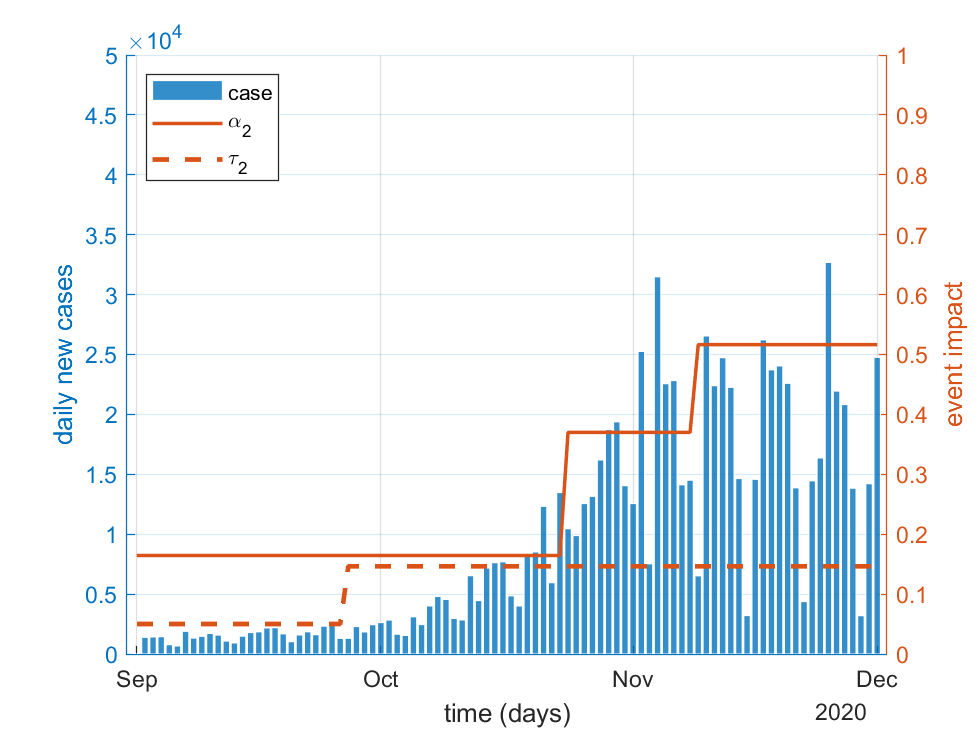

% the 2nd wave
clf; close all;
clear impact_alpha_1;
clear impact_tau_1;
clear legend;

time_delay = round(time_delay1);
impact_alpha_2 = ones(1, 92) * alpha1;
impact_tau_2 = ones(1, 92) * tau1;

NPI_ind = 1;
alp_ind = 1;
tau_ind = 1;

% figure--align event impact with COVID-19 curve
for ii=1:92
    if ii == 1
        impact_alpha_2(ii) = alpha1;
        impact_tau_2(ii) = tau1;
    else
        % update alpha and tau with NPIs
        if NPIs(ii, 2) == 1        % control event        
            impact_alpha_2(alp_ind + 1 : ii + time_delay - 1) = impact_alpha_2(alp_ind);
            impact_alpha_2(ii + time_delay) = impact_alpha_2(alp_ind) + NPI_matrix(NPI_ind);
            NPI_ind = NPI_ind + 1;
            alp_ind = ii + time_delay;
            impact_alpha_2(alp_ind : end) = impact_alpha_2(alp_ind);
        elseif NPIs(ii, 2) == 2    % lifting event
            impact_tau_2(tau_ind + 1 : ii + time_delay - 1) = impact_tau_2(tau_ind);
            impact_tau_2(ii + time_delay) = impact_tau_2(tau_ind) + NPI_matrix(NPI_ind);
            NPI_ind = NPI_ind + 1;
            tau_ind = ii + time_delay;
            impact_tau_2(tau_ind : end) = impact_tau_2(tau_ind);
        end
    end 
end

impact_alpha_2 = impact_alpha_2(1:92);
impact_tau_2 = impact_tau_2(1:92);

% daily new case
Confirmed2 = Confirmed(2:end);
daily_new_case(2:92) = Confirmed2 - Confirmed(1:91);
daily_new_case(1) = 0;

figure;
hold on;
yyaxis left
b = bar(time, daily_new_case, 'FaceColor', [0 0.4470 0.7410]);
set(b, 'edgecolor', [1,1,1]); 
alpha(0.8);
xlabel('time (days)');
ylabel('daily new cases');
ylim([0 50000]);

yyaxis right;
plot(time, impact_alpha_2, 'LineWidth', 1.5);
plot(time, impact_tau_2, 'LineWidth', 2);
ylabel('event impact');
ylim([0 1]);
legend('case', '\alpha_2', '\tau_2', 'Location', 'northwest');
grid on;
hold off;